# **Apomorphine Test Analysis - Cylindrical Arena**

**For studying stereotypical behaviors induced by apomorphine**

**Arena: 20 cm diameter x 40 cm height**

**Test duration: 30 minutes**

#### **A.Babaei**

clear; clc; close all;

%% ===== USER PARAMETERS =====
arena_diameter_cm = 20;      % Arena diameter in cm
arena_height_cm = 40;        % Arena height in cm
analysis_duration_min = 30;  % POST-injection analysis duration (minutes)

% Apomorphine-specific parameters
apomorphine_dose = 0.5;      % Dose in mg/kg (adjust based on your experiment)
injection_time = 0;          % Time 0 = injection time (start of recording)

% Movement thresholds (cm/s)
locomotion_threshold = 2.0;  % For general movement
stereotypy_threshold = 5.0;  % For repetitive/stereotyped movements
freezing_threshold = 0.5;    % For freezing behavior

% Zone parameters (NO PERIPHERAL ZONE)
central_zone_diameter_cm = 10;  % Central zone diameter (cm) - adjust as needed
use_peripheral_zone = false;    % Set to false since no peripheral zone

%% ===== DATA LOADING =====
fprintf('=== Apomorphine Test Analysis (Post-Injection Only) ===\n');

=== Apomorphine Test Analysis (Post-Injection Only) ===


fprintf('Arena: %.0f cm diameter x %.0f cm height\n', arena_diameter_cm, arena_height_cm);

Arena: 20 cm diameter x 40 cm height


fprintf('Analysis duration: %.0f minutes POST-INJECTION\n', analysis_duration_min);

Analysis duration: 30 minutes POST-INJECTION


fprintf('Apomorphine dose: %.2f mg/kg\n', apomorphine_dose);

Apomorphine dose: 0.50 mg/kg


fprintf('Recording starts at injection time (t=0)\n');

Recording starts at injection time (t=0)



% Check for tracking data
if ~exist('track', 'var')
    if exist('Out_Post.mat', 'file')
        load('Out_Post.mat');
        fprintf('Loaded Out_Post.mat\n');
    elseif exist('tracking_data.mat', 'file')
        load('tracking_data.mat');
        fprintf('Loaded tracking_data.mat\n');
    else
        % Try to select file interactively
        [filename, pathname] = uigetfile({'*.mat;*.csv', 'Tracking files'}, ...
                                         'Select POST-INJECTION tracking data');
        if isequal(filename, 0)
            error('No tracking data selected.');
        end
        load(fullfile(pathname, filename));
        fprintf('Loaded %s\n', filename);
    end
end

Loaded Out_APO_PD1.mat



%% ===== DATA VALIDATION =====
if ~exist('track', 'var')
    error('No ''track'' variable found in the loaded data.');
end

if ~isstruct(track)
    error('''track'' is not a struct (class: %s).', class(track));
end

fprintf('Available fields in track: %s\n', strjoin(fieldnames(track), ', '));

Available fields in track: Centroid, Head, Tail, Area, Axes, Tracked, Time, Eccentricity, EulerNumber, ConvexHull



%% ===== FRAME RATE & TIME BASE =====
if isfield(track, 'FrameRate')
    fps = track.FrameRate;
    fprintf('Using track.FrameRate: %.2f fps\n', fps);
elseif isfield(track, 'Time') && ~isempty(track.Time)
    Time = track.Time(:);
    fps = 1 / mean(diff(Time));
    fprintf('Calculated from track.Time: %.2f fps\n', fps);
else
    fps = 30; % Default assumption
    fprintf('Using default frame rate: %.0f fps\n', fps);
end

Calculated from track.Time: 29.97 fps



dt = 1/fps;  % Time per frame in seconds
total_frames_expected = analysis_duration_min * 60 * fps;
fprintf('Expected frames for %.0f min analysis: %d\n', analysis_duration_min, total_frames_expected);

Expected frames for 30 min analysis: 5.394605e+04



%% ===== POSITION DATA EXTRACTION =====
% Find centroid/position data
C = [];
if isfield(track, 'Centroid')
    C = double(track.Centroid);
    fprintf('Using Centroid data (%dx%d)\n', size(C,1), size(C,2));
elseif isfield(track, 'Head')
    C = double(track.Head);
    fprintf('Using Head data (%dx%d)\n', size(C,1), size(C,2));
elseif isfield(track, 'Body_Centroid')
    C = double(track.Body_Centroid);
    fprintf('Using Body_Centroid data (%dx%d)\n', size(C,1), size(C,2));
else
    error('No position data found in track structure.');
end

Using Centroid data (2x53942)



% Handle different coordinate formats
if size(C, 2) == 2 && size(C, 1) > 2
    x = C(:,1);
    y = C(:,2);
elseif size(C, 1) == 2 && size(C, 2) > 2
    x = C(1,:)';
    y = C(2,:)';
else
    error('Unknown coordinate format: %dx%d', size(C,1), size(C,2));
end

% Truncate to expected duration if needed
nFrames = min(total_frames_expected, length(x));
x = x(1:nFrames);
y = y(1:nFrames);
actual_duration_min = nFrames / fps / 60;
fprintf('Actual frames analyzed: %d (%.1f minutes)\n', nFrames, actual_duration_min);

Actual frames analyzed: 53942 (30.0 minutes)



%% ===== CALIBRATION =====
% Calculate arena bounds
min_x = min(x);
max_x = max(x);
min_y = min(y);
max_y = max(y);

arena_width_px = max_x - min_x;
arena_height_px = max_y - min_y;

% Add 5% margins for safety
margin_x = arena_width_px * 0.05;
margin_y = arena_height_px * 0.05;

min_x_arena = min_x - margin_x;
max_x_arena = max_x + margin_x;
min_y_arena = min_y - margin_y;
max_y_arena = max_y + margin_y;

arena_width_px = max_x_arena - min_x_arena;
arena_height_px = max_y_arena - min_y_arena;

% Pixel to cm conversion (using diameter)
px_to_cm = arena_diameter_cm / max(arena_width_px, arena_height_px);
fprintf('Pixel to cm conversion: 1 px = %.4f cm\n', px_to_cm);

Pixel to cm conversion: 1 px = 0.0322 cm



% Arena center in pixels
center_x = (min_x_arena + max_x_arena) / 2;
center_y = (min_y_arena + max_y_arena) / 2;
arena_radius_px = (max(arena_width_px, arena_height_px) / 2);

%% ===== ZONE DEFINITIONS (CENTRAL ONLY) =====
% Convert zone dimensions to pixels
central_radius_px = (central_zone_diameter_cm / 2) / px_to_cm;

% Calculate distance from center for each point
dist_from_center = sqrt((x - center_x).^2 + (y - center_y).^2);

% Zone masks (central zone only)
central_mask = dist_from_center <= central_radius_px;
noncentral_mask = ~central_mask;  % Everything outside central zone

% Calculate zone occupancy
t_seconds = (0:nFrames-1)' * dt;
t_minutes = t_seconds / 60;

time_in_central = sum(central_mask) * dt;
time_in_noncentral = sum(noncentral_mask) * dt;

percent_central = 100 * time_in_central / (nFrames * dt);
percent_noncentral = 100 * time_in_noncentral / (nFrames * dt);

fprintf('\n--- Zone Occupancy ---\n');


--- Zone Occupancy ---


fprintf('Central zone (%.1f cm diameter): %.1f%% of time\n', central_zone_diameter_cm, percent_central);

Central zone (10.0 cm diameter): 14.7% of time


fprintf('Non-central area: %.1f%% of time\n', percent_noncentral);

Non-central area: 85.3% of time



%% ===== SPEED & LOCOMOTION ANALYSIS =====
% Calculate speed
if nFrames > 1
    dx = diff(x);
    dy = diff(y);
    distance_px_frame = sqrt(dx.^2 + dy.^2);
    distance_cm_frame = [0; distance_px_frame] * px_to_cm;
else
    distance_cm_frame = zeros(nFrames, 1);
end

speed_cm_s = distance_cm_frame / dt;

% Smooth speed for analysis (5-frame moving average)
if nFrames >= 5
    kernel = ones(5,1)/5;
    speed_smoothed = conv(speed_cm_s, kernel, 'same');
    speed_smoothed(1:2) = speed_cm_s(1:2);
    speed_smoothed(end-1:end) = speed_cm_s(end-1:end);
else
    speed_smoothed = speed_cm_s;
end

total_distance_cm = sum(distance_cm_frame);

% Movement classification
moving = speed_smoothed > locomotion_threshold;
slow_moving = (speed_smoothed > freezing_threshold) & (speed_smoothed <= locomotion_threshold);
freezing = speed_smoothed <= freezing_threshold;
stereotypy = speed_smoothed > stereotypy_threshold;

time_moving = sum(moving) * dt;
time_slow = sum(slow_moving) * dt;
time_freezing = sum(freezing) * dt;
time_stereotypy = sum(stereotypy) * dt;

percent_moving = 100 * time_moving / (nFrames * dt);
percent_slow = 100 * time_slow / (nFrames * dt);
percent_freezing = 100 * time_freezing / (nFrames * dt);
percent_stereotypy = 100 * time_stereotypy / (nFrames * dt);

mean_speed = mean(speed_smoothed, 'omitnan');
max_speed = max(speed_smoothed);

fprintf('\n--- Locomotion Analysis ---\n');


--- Locomotion Analysis ---


fprintf('Total distance: %.1f cm\n', total_distance_cm);

Total distance: 16176.4 cm


fprintf('Mean speed: %.2f cm/s | Max speed: %.2f cm/s\n', mean_speed, max_speed);

Mean speed: 8.99 cm/s | Max speed: 317.28 cm/s


fprintf('Moving (>%.1f cm/s): %.1f%% of time\n', locomotion_threshold, percent_moving);

Moving (>2.0 cm/s): 73.0% of time


fprintf('Slow (%.1f-%.1f cm/s): %.1f%% of time\n', freezing_threshold, locomotion_threshold, percent_slow);

Slow (0.5-2.0 cm/s): 22.1% of time


fprintf('Freezing (<%.1f cm/s): %.1f%% of time\n', freezing_threshold, percent_freezing);

Freezing (<0.5 cm/s): 4.8% of time


fprintf('Stereotypy (>%.1f cm/s): %.1f%% of time\n', stereotypy_threshold, percent_stereotypy);

Stereotypy (>5.0 cm/s): 41.6% of time



%% ===== TIME-BINNED ANALYSIS (5-minute bins) =====
bin_duration_min = 5;  % Analyze in 5-minute bins
n_bins = floor(actual_duration_min / bin_duration_min);
bin_labels = cell(n_bins, 1);

fprintf('\n--- Time-Binned Analysis (%.0f-minute bins) ---\n', bin_duration_min);


--- Time-Binned Analysis (5-minute bins) ---



% Pre-allocate results
bin_means = zeros(n_bins, 1);
bin_moving = zeros(n_bins, 1);
bin_central = zeros(n_bins, 1);
bin_distance = zeros(n_bins, 1);

for bin = 1:n_bins
    start_frame = round((bin-1) * bin_duration_min * 60 * fps) + 1;
    end_frame = min(round(bin * bin_duration_min * 60 * fps), nFrames);
    
    bin_mask = (1:nFrames)' >= start_frame & (1:nFrames)' <= end_frame;
    
    if sum(bin_mask) > 0
        % Calculate metrics for this bin
        bin_speed = speed_smoothed(bin_mask);
        bin_moving_vec = moving(bin_mask);
        bin_central_vec = central_mask(bin_mask);
        bin_distance_vec = distance_cm_frame(bin_mask);
        
        bin_means(bin) = mean(bin_speed, 'omitnan');
        bin_moving(bin) = 100 * sum(bin_moving_vec) / sum(bin_mask);
        bin_central(bin) = 100 * sum(bin_central_vec) / sum(bin_mask);
        bin_distance(bin) = sum(bin_distance_vec);
        
        bin_labels{bin} = sprintf('%d-%d min', (bin-1)*bin_duration_min, bin*bin_duration_min);
        
        fprintf('\nBin %d (%s):\n', bin, bin_labels{bin});
        fprintf('  Mean speed: %.2f cm/s\n', bin_means(bin));
        fprintf('  %% moving: %.1f%%\n', bin_moving(bin));
        fprintf('  %% in center: %.1f%%\n', bin_central(bin));
        fprintf('  Distance: %.1f cm\n', bin_distance(bin));
    end
end


Bin 1 (0-5 min):


  Mean speed: 9.34 cm/s


  % moving: 63.2%


  % in center: 17.6%


  Distance: 2802.9 cm



Bin 2 (5-10 min):


  Mean speed: 9.13 cm/s


  % moving: 79.2%


  % in center: 15.6%


  Distance: 2739.3 cm



Bin 3 (10-15 min):


  Mean speed: 8.98 cm/s


  % moving: 75.6%


  % in center: 13.6%


  Distance: 2694.9 cm



Bin 4 (15-20 min):


  Mean speed: 9.26 cm/s


  % moving: 77.6%


  % in center: 14.5%


  Distance: 2778.4 cm



Bin 5 (20-25 min):


  Mean speed: 9.06 cm/s


  % moving: 73.3%


  % in center: 9.7%


  Distance: 2721.7 cm



%% ===== ROTATIONAL BEHAVIOR ANALYSIS =====
% Apomorphine often induces rotational behavior
if nFrames > 10
    % Calculate angular displacement
    angles = atan2(y - center_y, x - center_x);
    angular_velocity = diff(angles);
    
    % Unwrap angular differences
    angular_velocity(angular_velocity > pi) = angular_velocity(angular_velocity > pi) - 2*pi;
    angular_velocity(angular_velocity < -pi) = angular_velocity(angular_velocity < -pi) + 2*pi;
    
    angular_velocity_deg_s = rad2deg([0; angular_velocity]) / dt;
    
    % Count rotations (full 360° turns)
    cumulative_angle = cumsum(abs(angular_velocity));
    full_rotations = cumulative_angle(end) / (2*pi);
    
    % Direction preference
    clockwise_turns = sum(angular_velocity < 0);
    counterclockwise_turns = sum(angular_velocity > 0);
    rotation_bias = (clockwise_turns - counterclockwise_turns) / length(angular_velocity);
    
    % Rotations per minute
    rotations_per_min = full_rotations / actual_duration_min;
    
    fprintf('\n--- Rotational Analysis ---\n');
    fprintf('Total rotations: %.1f\n', full_rotations);
    fprintf('Rotations per minute: %.2f\n', rotations_per_min);
    fprintf('Rotation bias: %.3f (negative = clockwise preference)\n', rotation_bias);
    fprintf('Mean angular velocity: %.1f deg/s\n', mean(abs(angular_velocity_deg_s), 'omitnan'));
end


--- Rotational Analysis ---


Total rotations: 363.0


Rotations per minute: 12.10


Rotation bias: 0.226 (negative = clockwise preference)


Mean angular velocity: 72.6 deg/s


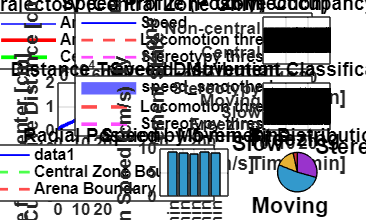


=== Analysis Complete ===


Results saved with prefix: Apomorphine_PostInj_30min_Dose0.50_2025-12-12_00-23-02


Summary saved to: Apomorphine_PostInj_30min_Dose0.50_2025-12-12_00-23-02_summary.csv


Detailed data saved to: Apomorphine_PostInj_30min_Dose0.50_2025-12-12_00-23-02_detailed_data.csv



%% ===== PLOTTING =====
% Set up figure
set(0, 'DefaultAxesFontSize', 12, 'DefaultAxesFontWeight', 'bold');
set(0, 'DefaultTextFontSize', 12, 'DefaultTextFontWeight', 'bold');

% Figure 1: Overview
fig1 = figure('Name', 'Apomorphine Test - Post-Injection Analysis', 'NumberTitle', 'off', ...
              'Position', [50 50 1400 900]);

% 1. Trajectory with central zone only
subplot(3,3,1);
plot(x, y, 'b-', 'LineWidth', 0.5, 'DisplayName', 'Animal Path');
hold on;

% Draw arena circle
theta = linspace(0, 2*pi, 100);
arena_circle_x = center_x + arena_radius_px * cos(theta);
arena_circle_y = center_y + arena_radius_px * sin(theta);
plot(arena_circle_x, arena_circle_y, 'r-', 'LineWidth', 2, 'DisplayName', 'Arena Boundary');

% Draw central zone only
central_circle_x = center_x + central_radius_px * cos(theta);
central_circle_y = center_y + central_radius_px * sin(theta);
plot(central_circle_x, central_circle_y, 'g--', 'LineWidth', 2, 'DisplayName', 'Central Zone');

xlabel('X [px]'); ylabel('Y [px]');
title('Animal Trajectory (Central Zone Only)');
legend('show', 'Location', 'best');
axis equal; grid on;

% 2. Speed over time
subplot(3,3,2);
plot(t_minutes, speed_smoothed, 'b-', 'LineWidth', 1, 'DisplayName', 'Speed');
hold on;
yline(locomotion_threshold, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Locomotion threshold');
yline(stereotypy_threshold, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Stereotypy threshold');
xlabel('Time [min]'); ylabel('Speed [cm/s]');
title('Speed Profile (Post-Injection)');
legend('show', 'Location', 'best');
grid on;
ylim([0 max(20, max_speed*1.1)]);

% 3. Zone occupancy over time (Central vs Non-central)
subplot(3,3,3);
zone_plot = zeros(size(t_minutes));
zone_plot(central_mask) = 1;
zone_plot(noncentral_mask) = 2;
plot(t_minutes, zone_plot, 'k-', 'LineWidth', 1);
xlabel('Time [min]'); ylabel('Zone');
title('Zone Occupancy');
yticks([1 2]);
yticklabels({'Central', 'Non-central'});
ylim([0.5 2.5]);
grid on;

% 4. Cumulative distance
subplot(3,3,4);
cumulative_distance = cumsum(distance_cm_frame);
plot(t_minutes, cumulative_distance, 'b-', 'LineWidth', 2);
xlabel('Time [min]'); ylabel('Cumulative Distance [cm]');
title('Distance Traveled');
grid on;

% 5. Speed histogram
subplot(3,3,5);
histogram(speed_smoothed, 40, 'FaceColor', 'blue', 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xline(locomotion_threshold, 'r--', 'LineWidth', 2, 'DisplayName', 'Locomotion threshold');
xline(stereotypy_threshold, 'm--', 'LineWidth', 2, 'DisplayName', 'Stereotypy threshold');
xlabel('Speed [cm/s]'); ylabel('Probability');
title('Speed Distribution');
legend('show', 'Location', 'best');
grid on;

% 6. Movement state over time
subplot(3,3,6);
movement_state = zeros(size(t_minutes));
movement_state(freezing) = 1;
movement_state(slow_moving) = 2;
movement_state(moving) = 3;
movement_state(stereotypy) = 4;
plot(t_minutes, movement_state, 'k-', 'LineWidth', 1);
xlabel('Time [min]'); ylabel('Movement State');
title('Movement Classification');
yticks([1 2 3 4]);
yticklabels({'Freezing', 'Slow', 'Moving', 'Stereotypy'});
ylim([0.5 4.5]);
grid on;

% 7. Distance from center over time
subplot(3,3,7);
plot(t_minutes, dist_from_center * px_to_cm, 'b-', 'LineWidth', 1);
hold on;
yline(central_radius_px * px_to_cm, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Central Zone Boundary');
yline(arena_radius_px * px_to_cm, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Arena Boundary');
xlabel('Time [min]'); ylabel('Distance from Center [cm]');
title('Radial Position');
legend('show', 'Location', 'best');
grid on;

% 8. Time-binned analysis (bar plots)
subplot(3,3,8);
if n_bins > 0
    x_pos = 1:n_bins;
    bar(x_pos, bin_means, 'FaceColor', [0.2 0.6 0.8]);
    xlabel('Time Bin'); ylabel('Mean Speed (cm/s)');
    title(sprintf('Speed by %.0f-min Bins', bin_duration_min));
    xticks(x_pos);
    xticklabels(bin_labels);
    grid on;
else
    text(0.5, 0.5, 'Insufficient data for time bins', ...
         'HorizontalAlignment', 'center', 'FontSize', 12);
    axis off;
end

% 9. Summary pie chart
subplot(3,3,9);
movement_data = [percent_freezing, percent_slow, percent_moving, percent_stereotypy];
labels = {'Freezing', 'Slow', 'Moving', 'Stereotypy'};
colors = [0.8 0.2 0.2; 0.9 0.7 0.2; 0.2 0.6 0.8; 0.6 0.2 0.8];
pie(movement_data, labels);
colormap(colors);
title('Movement Distribution (%)');

%% ===== SAVE RESULTS =====
timestamp = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');
baseFilename = sprintf('Apomorphine_PostInj_%.0fmin_Dose%.2f_%s', ...
                      analysis_duration_min, apomorphine_dose, timestamp);

try
    % Save figures
    saveas(fig1, sprintf('%s_overview.fig', baseFilename));
    saveas(fig1, sprintf('%s_overview.png', baseFilename));
    
    % Save detailed data
    results_table = table(t_seconds, t_minutes, x, y, speed_smoothed, ...
                         distance_cm_frame, moving, freezing, stereotypy, ...
                         central_mask, dist_from_center * px_to_cm, ...
                         'VariableNames', {'Time_s', 'Time_min', 'X_px', 'Y_px', ...
                         'Speed_cm_s', 'Distance_cm', 'IsMoving', 'IsFreezing', ...
                         'IsStereotypy', 'InCentral', 'DistanceFromCenter_cm'});
    
    writetable(results_table, sprintf('%s_detailed_data.csv', baseFilename));
    
    % Save time-binned results
    if n_bins > 0
        bin_table = table(bin_labels, bin_means, bin_moving, bin_central, bin_distance, ...
                         'VariableNames', {'TimeBin', 'MeanSpeed_cm_s', 'PercentMoving', ...
                         'PercentCentral', 'Distance_cm'});
        writetable(bin_table, sprintf('%s_timebins.csv', baseFilename));
    end
    
    % Save summary statistics
    summary_data = struct();
    summary_data.ArenaDiameter_cm = arena_diameter_cm;
    summary_data.ArenaHeight_cm = arena_height_cm;
    summary_data.AnalysisDuration_min = actual_duration_min;
    summary_data.ApomorphineDose_mg_kg = apomorphine_dose;
    summary_data.TotalDistance_cm = total_distance_cm;
    summary_data.MeanSpeed_cm_s = mean_speed;
    summary_data.MaxSpeed_cm_s = max_speed;
    summary_data.PercentMoving = percent_moving;
    summary_data.PercentFreezing = percent_freezing;
    summary_data.PercentStereotypy = percent_stereotypy;
    summary_data.PercentCentral = percent_central;
    summary_data.PercentNoncentral = percent_noncentral;
    
    if exist('full_rotations', 'var')
        summary_data.TotalRotations = full_rotations;
        summary_data.RotationsPerMin = rotations_per_min;
        summary_data.RotationBias = rotation_bias;
    end
    
    % Convert struct to table for CSV export
    summary_table = struct2table(summary_data);
    writetable(summary_table, sprintf('%s_summary.csv', baseFilename));
    
    % Save as MAT file for later use
    save(sprintf('%s_results.mat', baseFilename), 'results_table', 'summary_data', ...
         'speed_smoothed', 'central_mask', 'dist_from_center');
    
    fprintf('\n=== Analysis Complete ===\n');
    fprintf('Results saved with prefix: %s\n', baseFilename);
    fprintf('Summary saved to: %s_summary.csv\n', baseFilename);
    fprintf('Detailed data saved to: %s_detailed_data.csv\n', baseFilename);
    
catch ME
    warning('Error saving files: %s', ME.message);
    fprintf('Analysis complete but some files may not have been saved.\n');
end


%% ===== PRINT FINAL SUMMARY =====
fprintf('\n===============================================\n');

fprintf('APOMORPHINE TEST - POST-INJECTION SUMMARY\n');

APOMORPHINE TEST - POST-INJECTION SUMMARY


fprintf('Dose: %.2f mg/kg | Duration: %.1f min\n', apomorphine_dose, actual_duration_min);

Dose: 0.50 mg/kg | Duration: 30.0 min


fprintf('===============================================\n');

fprintf('Total distance: %.0f cm\n', total_distance_cm);

Total distance: 16176 cm


fprintf('Mean speed: %.2f cm/s | Max speed: %.2f cm/s\n', mean_speed, max_speed);

Mean speed: 8.99 cm/s | Max speed: 317.28 cm/s


fprintf('Time moving: %.1f%%\n', percent_moving);

Time moving: 73.0%


fprintf('Time freezing: %.1f%%\n', percent_freezing);

Time freezing: 4.8%


fprintf('Stereotypical behavior: %.1f%%\n', percent_stereotypy);

Stereotypical behavior: 41.6%


fprintf('Center occupancy: %.1f%%\n', percent_central);

Center occupancy: 14.7%


if exist('full_rotations', 'var')
    fprintf('Total rotations: %.1f (%.2f rotations/min)\n', full_rotations, rotations_per_min);
end

Total rotations: 363.0 (12.10 rotations/min)


fprintf('===============================================\n');